# imLens Calibration Practicum 

This demo goes though the intrinsic lens calibration to correct for lens distortion. It is specific to each camera and lens. The code is meant to be run line by line while following the lens calibration practicum presentation. 

## Set up paths and basic parameters

clear all 
close all

% change directory to where calibration images are located 
demo_dir=uigetdir('/Volumes/STONE-IG-3/IG-STONE/calibration_camera2/images_12_3','Choose the directory where calibration images are located');
cd(demo_dir)

% add the path to where the caltech toolbox is located
warning('off')
caltech_dir=uigetdir('/Users/annagoldman/Desktop/RESEARCH/imgcalibration/TOOLBOX_calib','Choose the directory where the Caltech Toolbox is located (TOOLBOX_calib)');
addpath(genpath(caltech_dir))

%% Set Parameters
% change default figure size
set(0, 'DefaultFigurePosition', [300   100   1000   700]);

% Set the default to calculate all 5 distortion coefficients
est_dist = [1;1;1;1;1];  

## Run the Caltech GUI

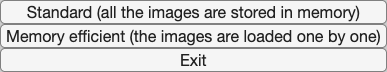

calib_gui;

% Click "Standard" for computers with >4 GB of RAM and "Memory Efficient" for slower computers'

%% 1st step: Find images
%%
% # Click "Image Names" to find images in the CURRENT directory
% # Enter "c1_" as image prefix name
% # Enter "j" for jpegs

%% 2nd step: Extract grid corners
%%
% # Click "Extract Grid Corners" to start the calibration
% # Hit "Enter" to process all images
% # Hit "Enter" 3 times to chose default options for corner finding
% # Click the 4 grid corners in a clock wise direction 
% # Type "29" for dX and dY as the size of the squares
% # Hit "Enter" for default of no distortion

% %%***For Demo Purposes Only:
% load 'Calib_Results_Demo.mat'


%% 3rd step: Calibration 
% # Click "Calibration" to start the calibration

% Calibration coefficients now calculated

%% 4th step: Check Results
% Change inputs to decrease error in calibration

% # Click "Analyse Error"
%   If error is high (Striving for a pixel error < 1), Click "Recomp.
%   corners" to use a smaller window to find the corners
%
% # Click "Analyse Error"
%   Click outlier points to determine which images to remove from calibration calculation
%
% # Click "Add/Suppress images
%   Remove images with high pixel error determined in the previous step
%
% # Click "Calibration" to RECOMPUTE the calibration with new inputs
%
%% 5th step: Plot Results
% Plot output figures with distortion information
% # Click "Show Extrinsic" 
% # Click "Reproject on Images"
%
%% 6th step: Save GUI data & exit
% # Click "Save" 
% # Click "Exit" 

%% Plot Final Results
visualize_distortions

Unrecognized function or variable 'nx'.

Error in visualize_distortions (line 11)
[mx,my] = meshgrid(0:nx/20:(nx-1),0:ny/20:(ny-1));
^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

%% Ready for use with CIRN-Quantitative-Coastal-Imaging-Toolbox > A_formatIntrinsics

%
%   Copyright (C) 2017  Coastal Imaging Research Network
%                       and Oregon State University

%    This program is free software: you can redistribute it and/or  
%    modify it under the terms of the GNU General Public License as 
%    published by the Free Software Foundation, version 3 of the 
%    License.

%    This program is distributed in the hope that it will be useful,
%    but WITHOUT ANY WARRANTY; without even the implied warranty of
%    MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the
%    GNU General Public License for more details.

%    You should have received a copy of the GNU General Public License
%    along with this program.  If not, see
%                                <http://www.gnu.org/licenses/>.

% CIRN: https://coastal-imaging-research-network.github.io/
% CIL:  http://cil-www.coas.oregonstate.edu
%
%key cBathy
%

